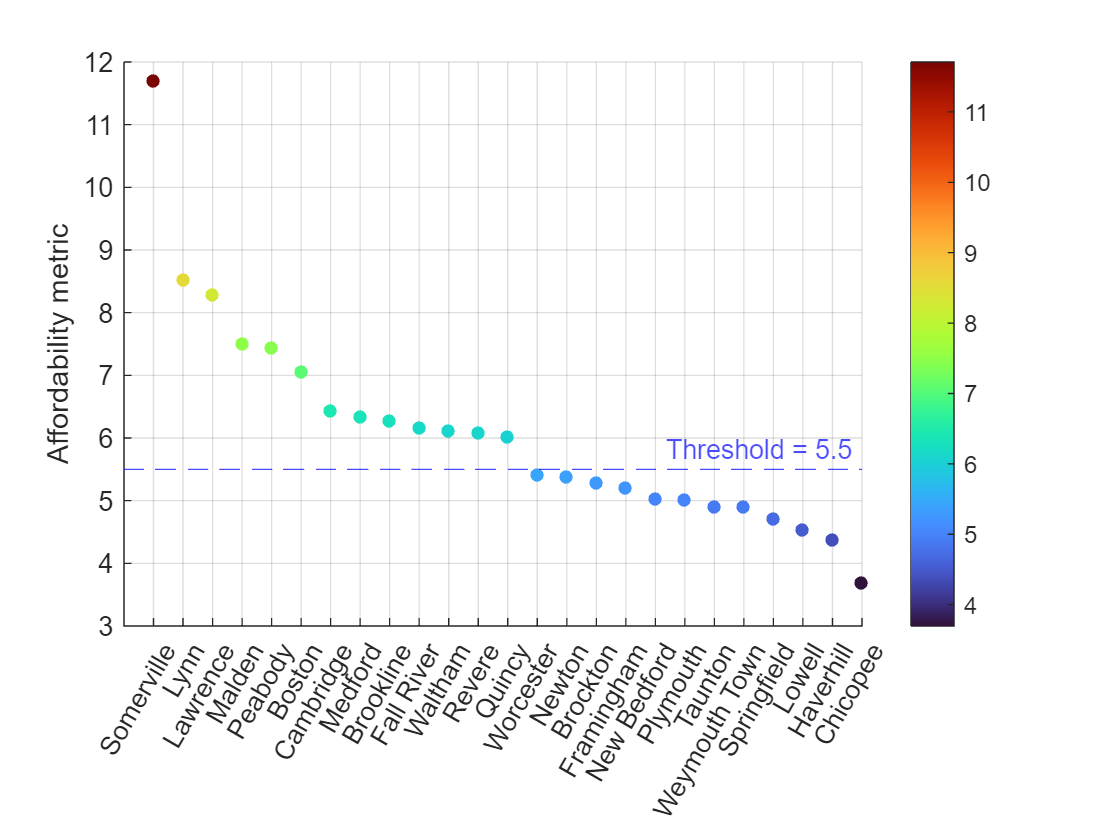

affordability = homeprices ./ incomes;
municipalities = table2array(Data(2:end, "municipality"));

n = length(affordability);

% sort affordability, keep order index, replace affordability with sorted vector
[affordability, ix] = sort(affordability, "descend");

% reorder municipalities to match
municipalities = municipalities(ix);  

color = affordability;
scatter(1:n, affordability, 25, color, "filled")
yline(5.5, "--b", "Threshold = 5.5")
colormap("turbo");
ylabel("Affordability metric")
xticks([1:25]);
xticklabels(municipalities);
xtickangle(60);
colorbar
grid

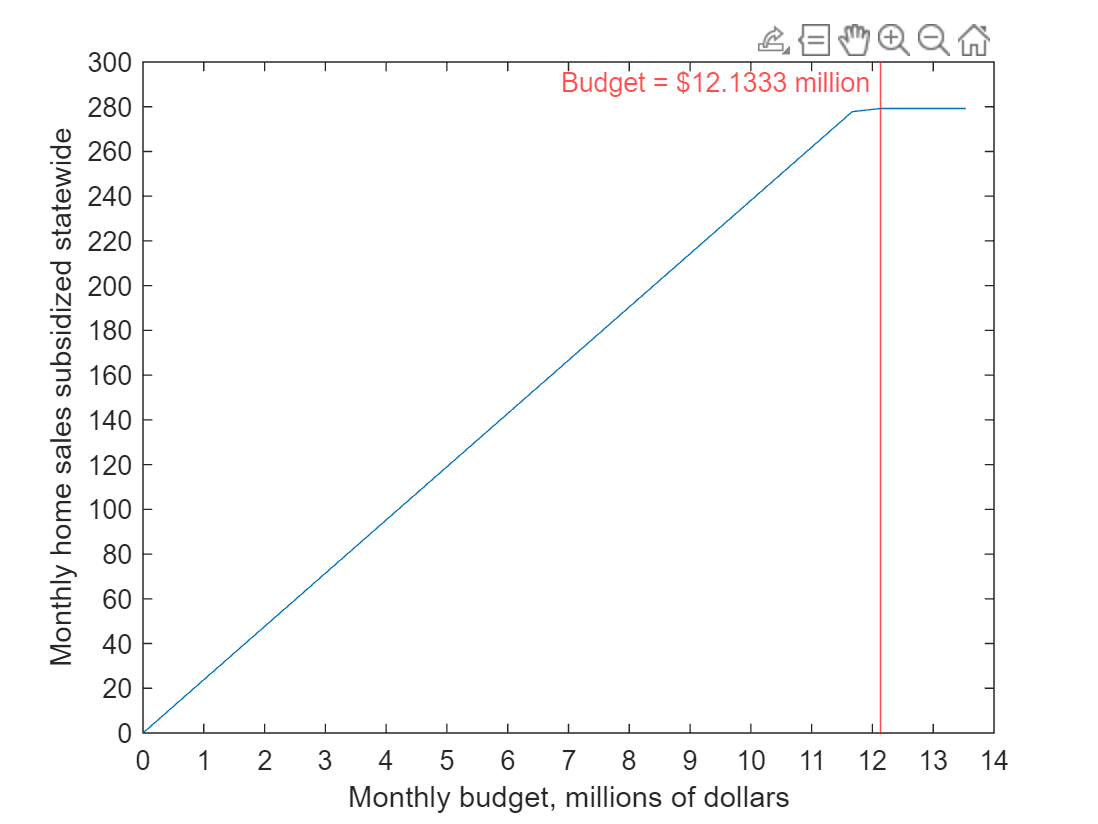

n=optimal_idx+3;
figure(1)
plot(budj(1:n)/1e6,obj(1:n))
ylabel("Monthly home sales subsidized statewide")
ylim([0 300])
yticks(0:20:300)
xticks(0:14)
xline(optimal_budj/1e6, "r", ...
    append("Budget = $", string(optimal_budj/1e6), " million"), ...
    LabelHorizontalAlignment="left", LabelOrientation="horizontal")
xlabel("Monthly budget, millions of dollars")

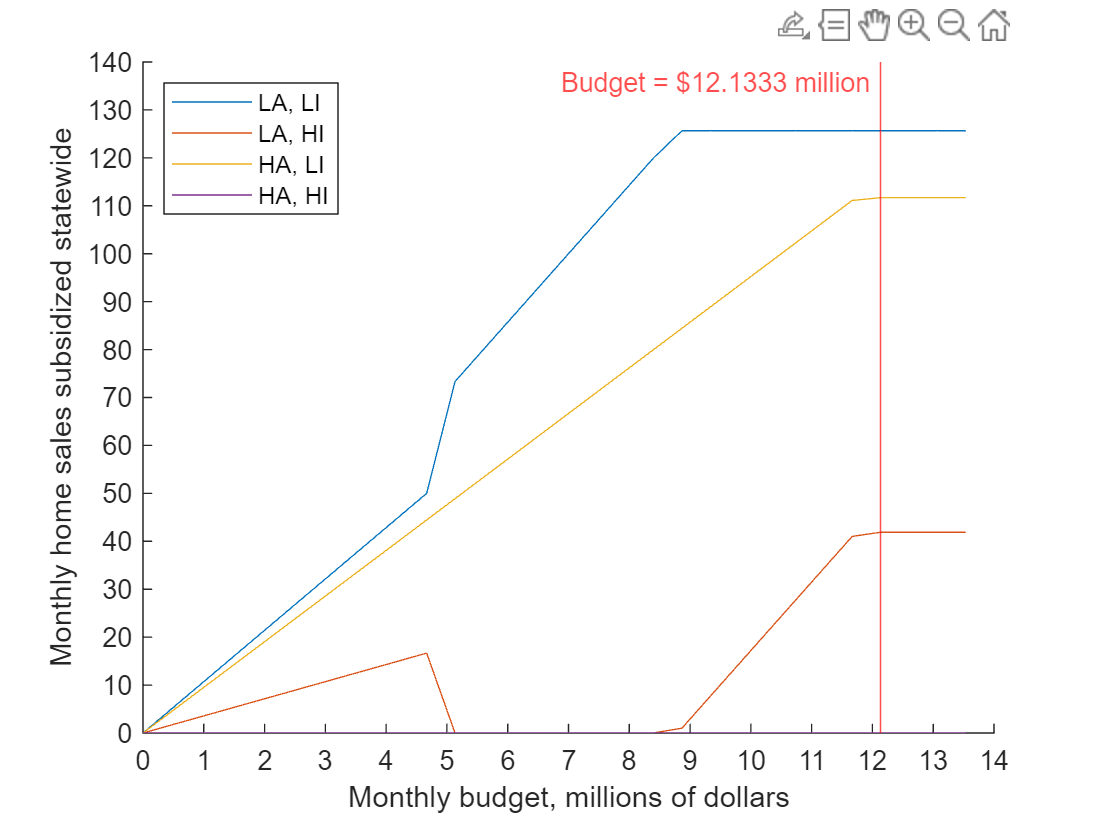

figure(2)
hold on
plot(budj(1:n)/1e6,results(1,1:n))
plot(budj(1:n)/1e6,results(2,1:n));
plot(budj(1:n)/1e6,results(3,1:n));
plot(budj(1:n)/1e6,results(4,1:n));

ylabel("Monthly home sales subsidized statewide")
ylim([0 140])
yticks(0:10:140)
xticks(0:14)
xline(optimal_budj/1e6, "r", ...
    append("Budget = $", string(optimal_budj/1e6), " million"), ...
    LabelHorizontalAlignment="left", LabelOrientation="horizontal")
xlabel("Monthly budget, millions of dollars")

legend("LA, LI","LA, HI", ...
    "HA, LI","HA, HI",'', location='northwest')

hold off